%Supercapacitor current controller
V_dc=48;
C=220e-6;
R=46;
L_sc=2.3e-3;
D_sc=0.5;
s = tf('s');
Gsc_itod=(((s*V_dc*C)+(2*V_dc/R)))/((s^2*L_sc*C)+(s*(L_sc/R))+(1-D_sc)^2)

Gsc_itod =
 
        0.01056 s + 2.087
  -----------------------------
  5.06e-07 s^2 + 5e-05 s + 0.25
 
Continuous-time transfer function.
Model Properties


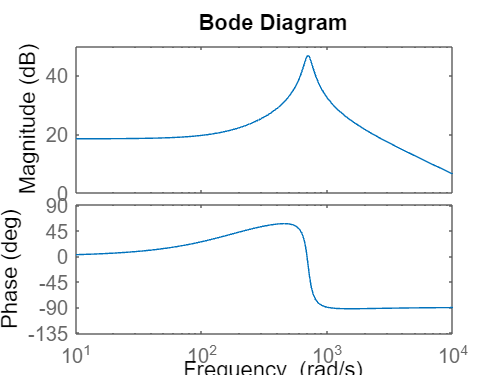

bode(Gsc_itod);

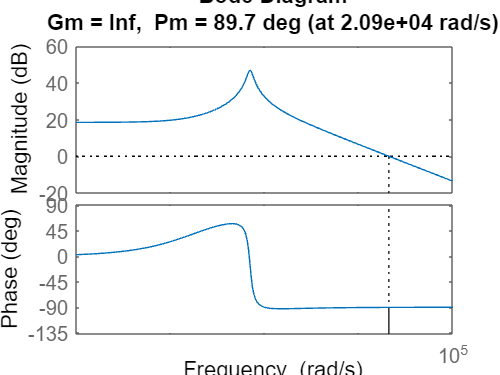

margin(Gsc_itod);


kp=0.22;
ki=800;
Gbv=(s*kp+ki)/(s);
Gtotal=Gbitod1*Gbv;

Unrecognized function or variable 'Gbitod1'.

bode(Gtotal);
margin(Gtotal);
% Plot Bode plot for both systems on the same figure
figure;
bode(Gbitod1); % plot first system
hold on;    % hold the current plot
bode(Gtotal); % plot second system
hold off;   % release the hold
% Optional: add legend to identify systems
legend('Gbitod1', 'Gtotal');
